# Signal Processing III

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2019-12-25

### Convotluion 1 (Square Wave)

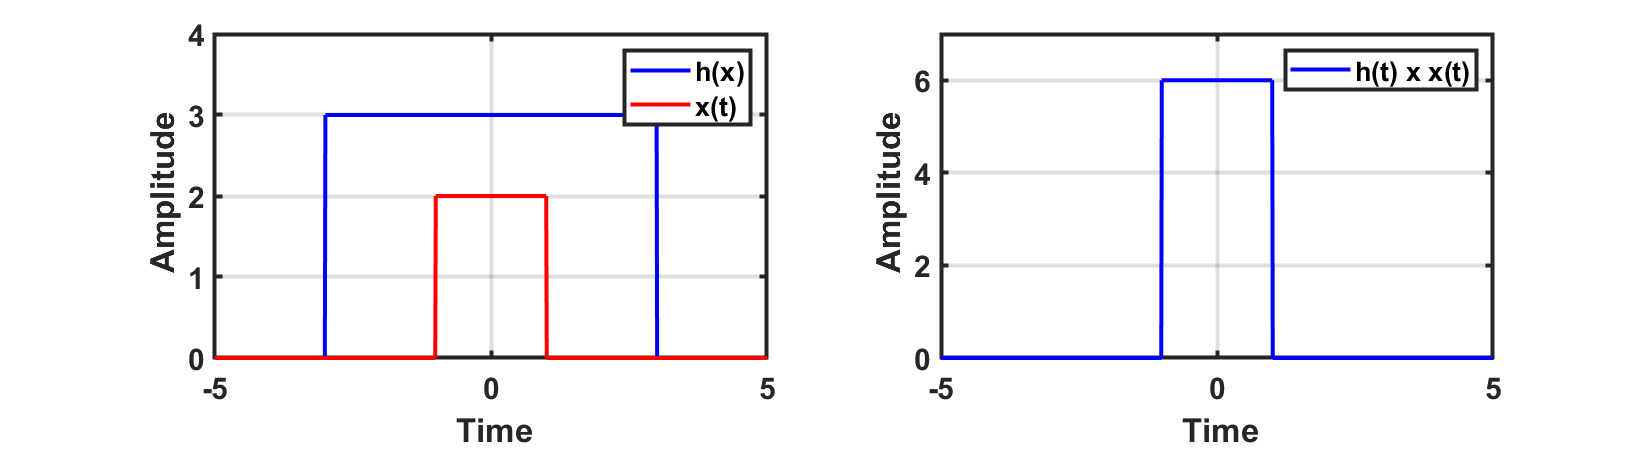

clear; clc ; close all;

syms t   

a = 3; b = 3;
sig1 = @(t) a*(abs(t)<=b) + 0;

a = 2; b = 1;
sig2 = @(t) a*(abs(t)<=b) + 0;

t = -10:0.01:10;

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 300]);

subplot(121); plot(t,sig1(t),'-b', 'linewidth', 2);hold on;
plot(t,sig2(t),'-r', 'linewidth', 2);
legend('h(x)', 'x(t)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 4])
xlabel('\bf Time');xlim([-5 5])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(122); plot(t,sig1(t).*sig2(t),'-b', 'linewidth', 2);hold on;
legend('h(t) x x(t)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 7])
xlabel('\bf Time');xlim([-5 5])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

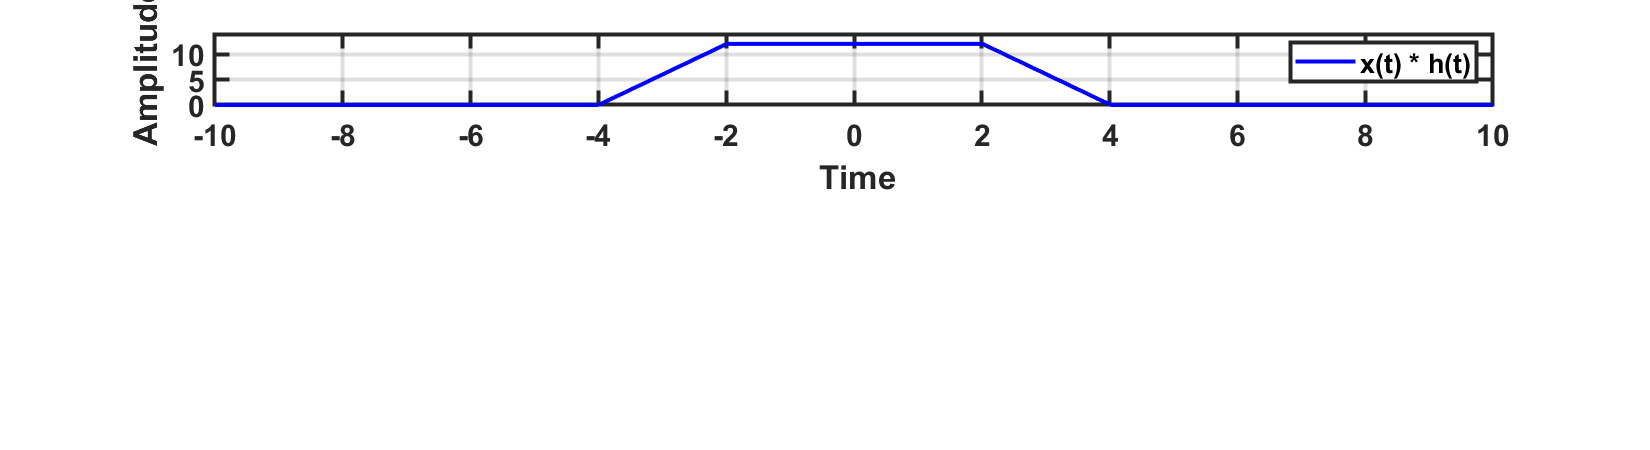


fig2 = figure(2);
set(fig2,'Position', [100 100 1100 300]);

sig_conv = conv(sig1(t), sig2(t))*0.01;
subplot(411); plot(t,sig_conv((floor(numel(sig_conv)/4)):floor(numel(sig_conv)/4)*3),'-b', 'linewidth', 2);hold on;
legend('x(t) * h(t)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 14])
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

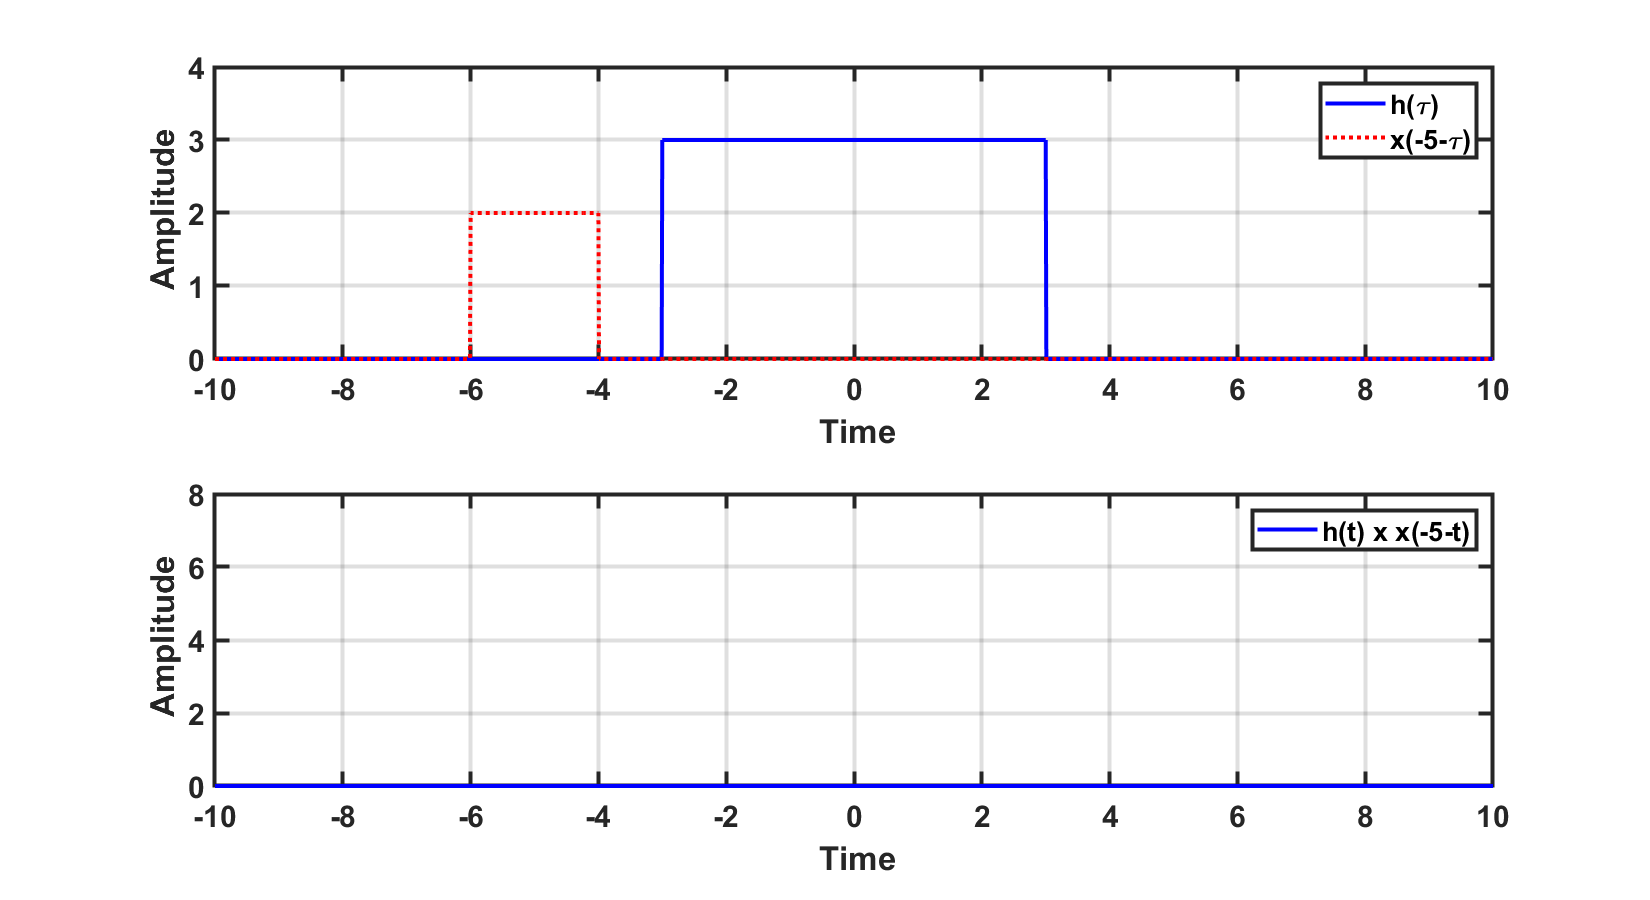



fig3 = figure(3);
set(fig3,'Position', [100 100 1100 600]);

subplot(211); plot(t,sig1(t),'-b', 'linewidth', 2);hold on;
plot(t,sig2(-5-t),':r', 'linewidth', 2);hold on;
legend('h(\tau)', 'x(-5-\tau)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 4])
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(212); plot(t,sig1(t).*sig2(-5-t),'-b', 'linewidth', 2);
legend('h(t) x x(-5-t)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 8]);
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

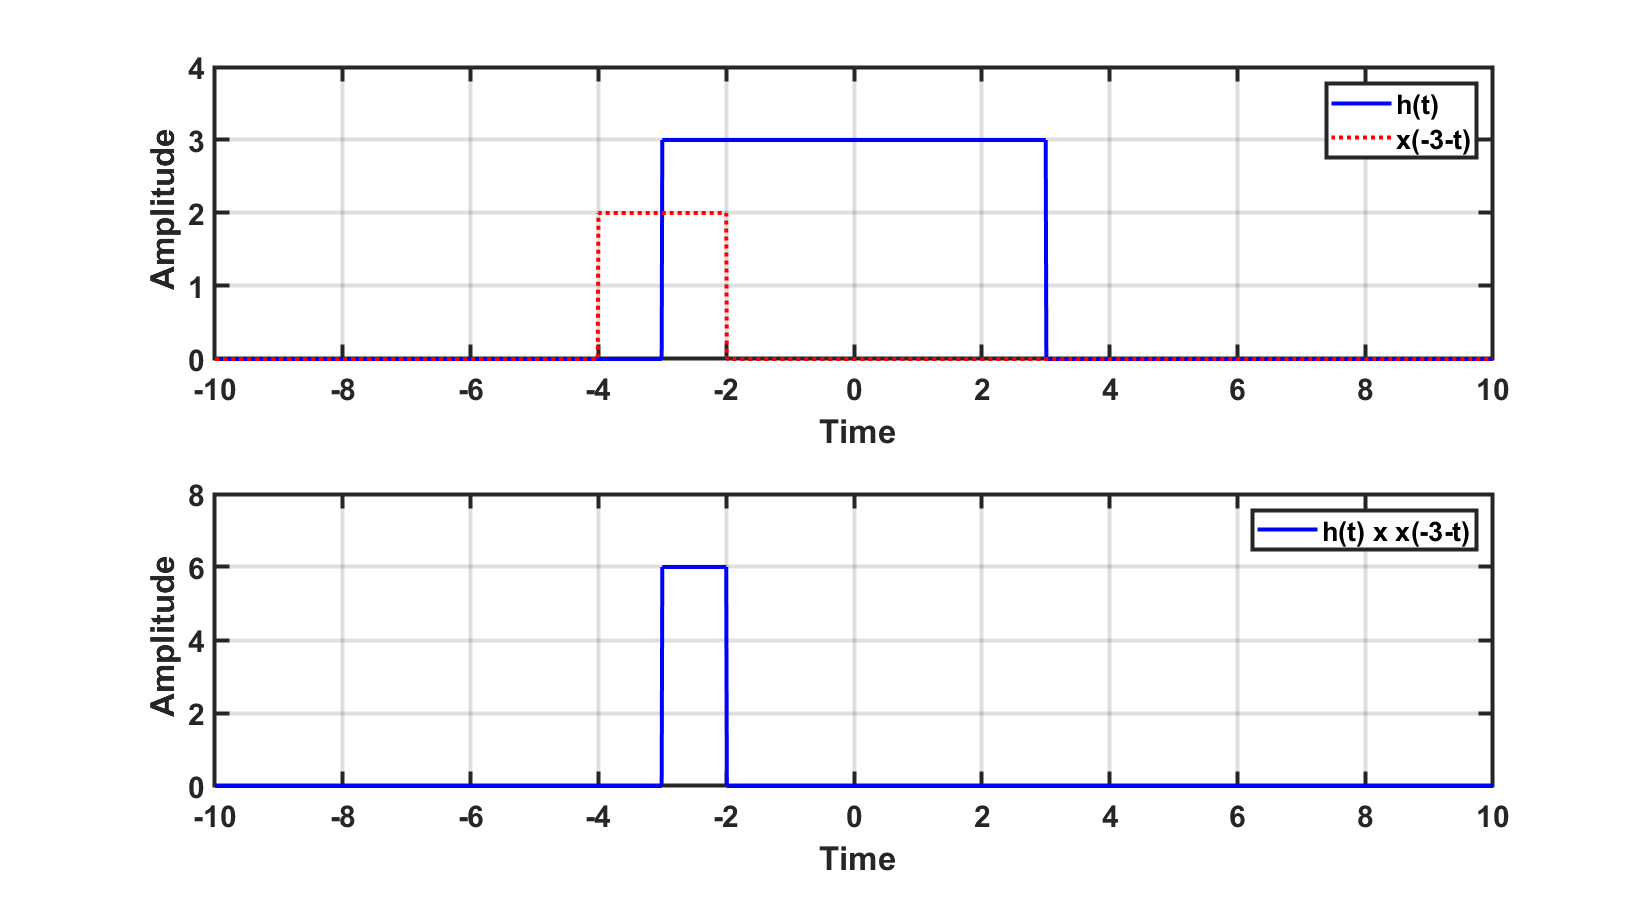



fig4 = figure(4);
set(fig4,'Position', [100 100 1100 600]);

subplot(211); plot(t,sig1(t),'-b', 'linewidth', 2);hold on;
plot(t,sig2(-3-t),':r', 'linewidth', 2);hold on;
legend('h(\tau)', 'x(-3-\tau)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 4])
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(212); plot(t,sig1(t).*sig2(-3-t),'-b', 'linewidth', 2);
legend('h(\tau) x x(-3-\tau)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 8]);
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

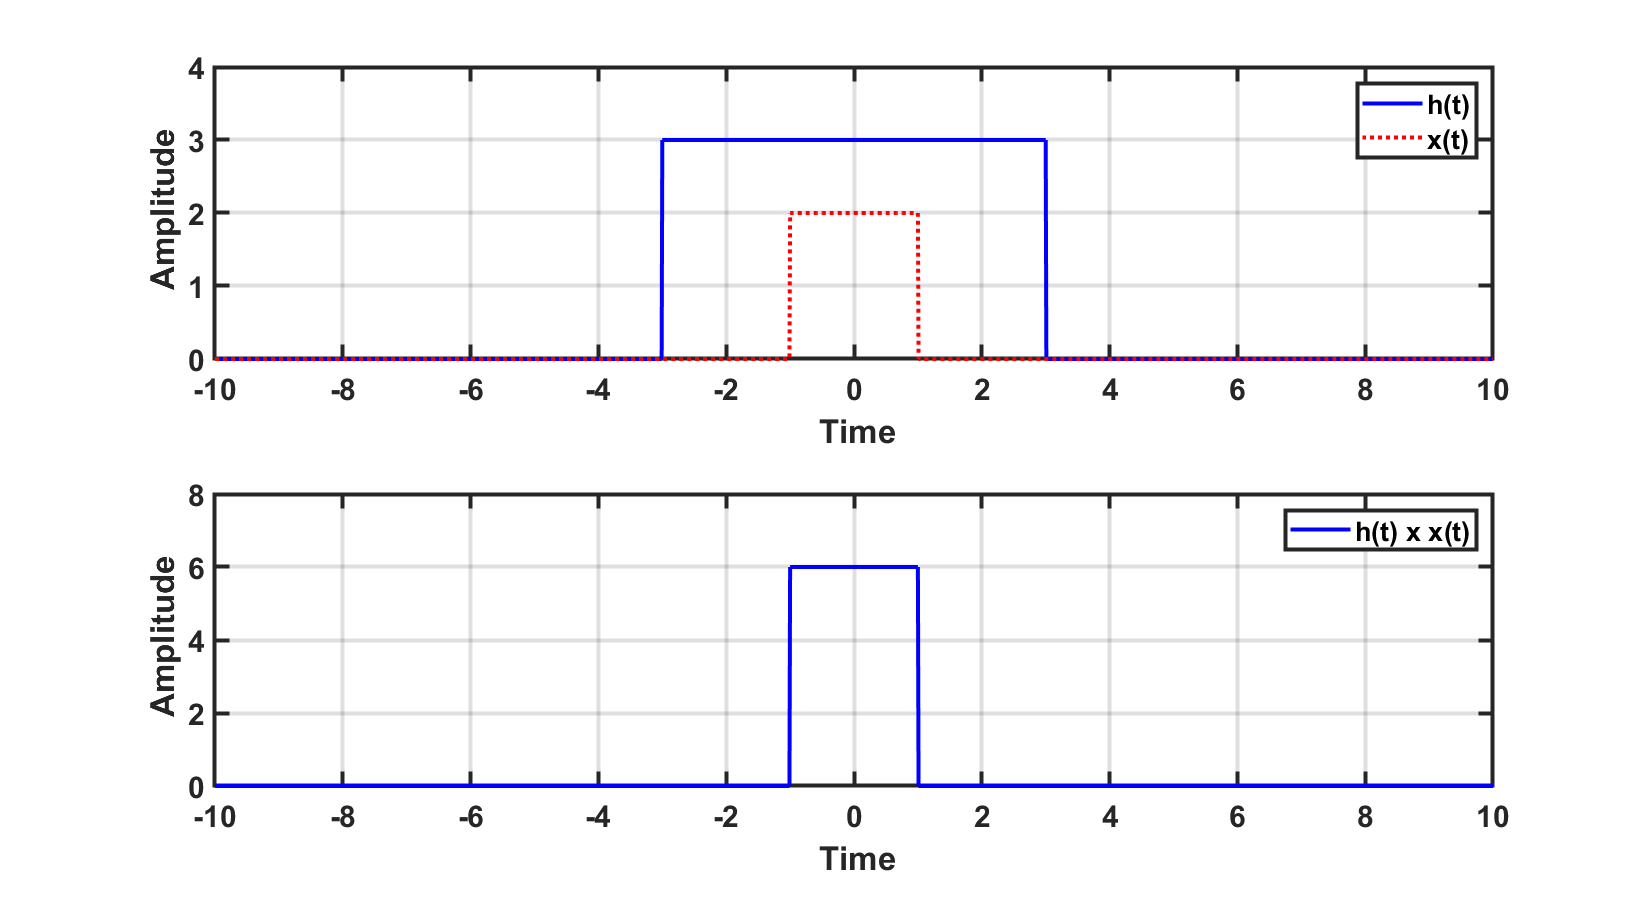



fig5 = figure(5);
set(fig5,'Position', [100 100 1100 600]);

subplot(211); plot(t,sig1(t),'-b', 'linewidth', 2);hold on;
plot(t,sig2(t),':r', 'linewidth', 2);hold on;
legend('h(\tau)', 'x(\tau)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 4])
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(212); plot(t,sig1(t).*sig2(t),'-b', 'linewidth', 2);
legend('h(\tau) x x(\tau)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 8]);
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

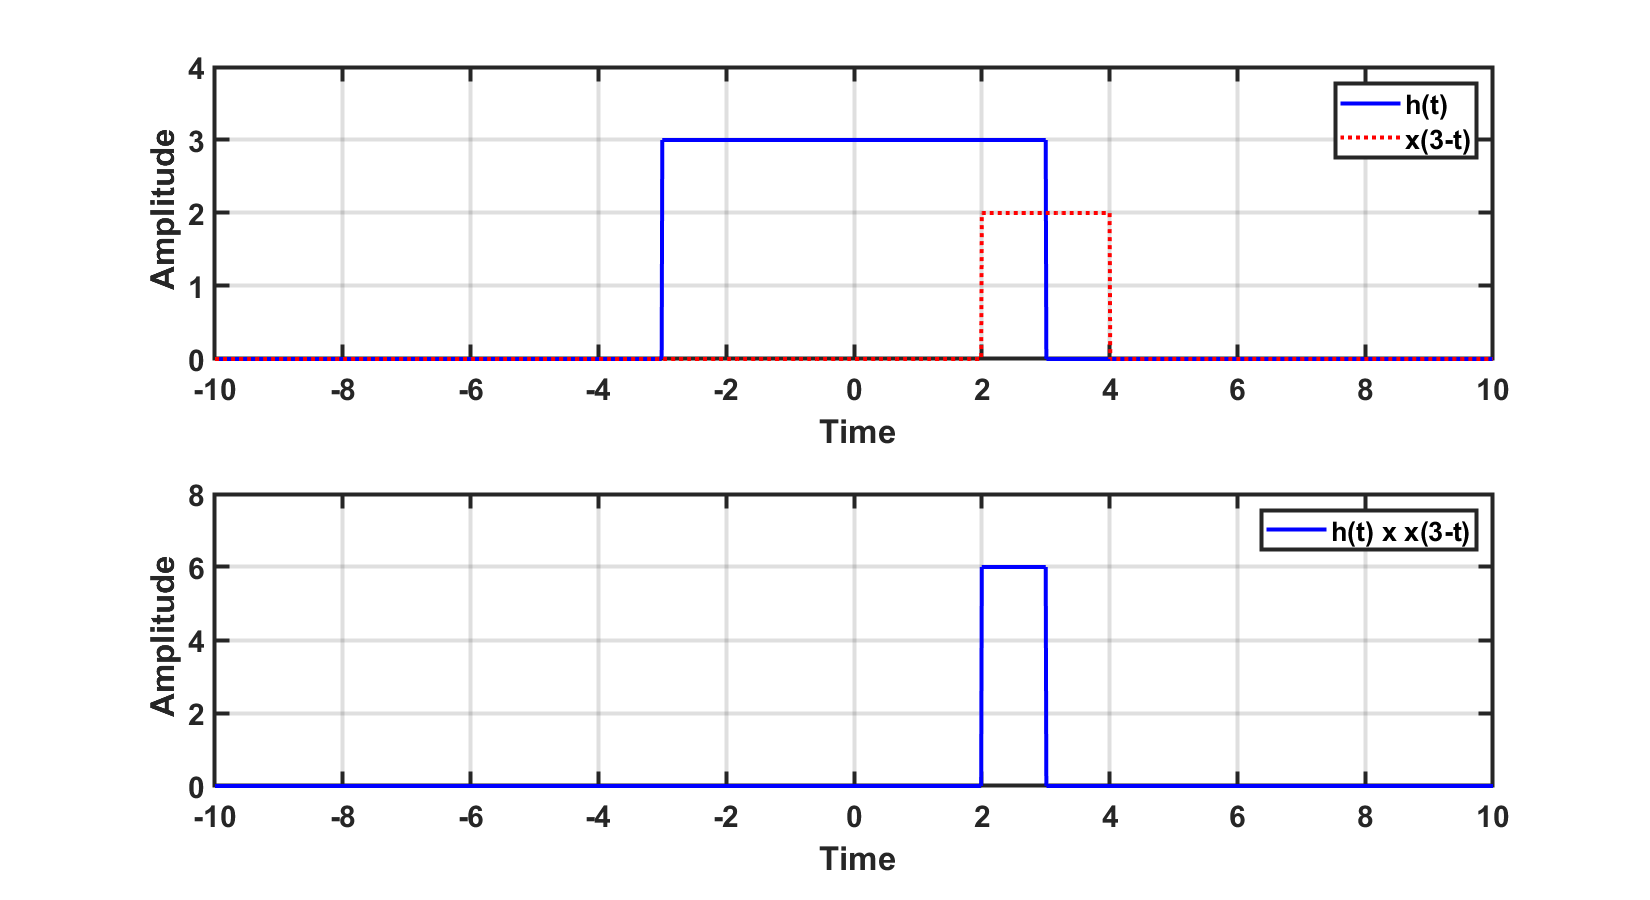



fig6 = figure(6);
set(fig6,'Position', [100 100 1100 600]);

subplot(211); plot(t,sig1(t),'-b', 'linewidth', 2);hold on;
plot(t,sig2(3-t),':r', 'linewidth', 2);hold on;
legend('h(\tau)', 'x(3-\tau)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 4])
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(212); plot(t,sig1(t).*sig2(3-t),'-b', 'linewidth', 2);
legend('h(\tau) x x(3-\tau)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 8]);
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### Convotluion 2 (Damped Symmetrically Oscillating Function)

clear; clc ; close all;

a = 3;
f_0 = 4;

x1 = @(t) exp(-a.*abs(t));
x2 = @(t) cos(2*pi*f_0*t);

x3 = @(t) x1(t).*x2(t);

x1_in = @(t, f) x1(t)*exp(-sqrt(-1)*2*pi*f*t);
X1f = @(f) integral(@(t) x1_in(t, f), -inf, inf,'ArrayValued',true);

t = -2:0.01:2;
f = [-12:0.01:12] +realmin;

fig1 = figure(1);
set(fig1,'Position', [100 100 800 900]);

subplot(311); plot(t,x1(t),'-b', 'linewidth', 2);hold on;
plot(t,x2(t),'-r', 'linewidth', 2);
legend('x1', 'x2'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-1 1])
xlabel('\bf Time');xlim([-2 2])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(312); plot(t,x1(t).*x2(t),'-b', 'linewidth', 2);hold on;
legend('x1 x x2'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-1 1])
xlabel('\bf Time');xlim([-2 2])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(313); plot(f,abs(X3f(f)),'-b', 'linewidth', 2);
legend('X(f)'); axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf f');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### Effects of Windowing on the Frequency Signal (Modulus)

clear; close all; clc;

T = 0.6;
[sig, hann, rectw, fs] = hann_rect_window_example(T); % you need to have this file in the folder.

fig1 = figure(1);
set(fig1,'Position', [100 100 1300 300]);

subplot(131); plot(sig.t,sig.x, 'b', 'linewidth', 1);
axis tight;grid on; hold off;
ylabel('\bf x(t)'); 
xlabel('\bf Time(s)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

subplot(132);stem(rectw.f(1:rectw.N/2+1), abs(rectw.X(1:rectw.N/2+1)/fs/T), 'r:', 'linewidth', 1); hold on;
plot(rectw.fz(1:rectw.Nz/2+1), abs(rectw.Xz(1:rectw.Nz/2+1)/fs/T), 'b', 'linewidth', 1)
line([10 10],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([20 20],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([21 21],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
axis tight;grid on; hold off;
ylabel('\bf X(f)'); 
xlabel('\bf f (Hz)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

subplot(133);stem(hann.f(1:hann.N/2+1), abs(hann.X(1:hann.N/2+1)/fs/T), 'r:', 'linewidth', 1); hold on;
plot(hann.fz(1:hann.Nz/2+1), abs(hann.Xz(1:hann.Nz/2+1)/fs/T), 'b', 'linewidth', 1)
line([10 10],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([20 20],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([21 21],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
axis tight;grid on; hold off;
ylabel('\bf X(f)'); 
xlabel('\bf f (Hz)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

T = 1;
[sig, hann, rectw, fs] = hann_rect_window_example(T);

fig2 = figure(2);
set(fig2,'Position', [100 100 1300 300]);

subplot(131); plot(sig.t,sig.x, 'b', 'linewidth', 1);
axis tight;grid on; hold off;
ylabel('\bf x(t)'); 
xlabel('\bf Time(s)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

subplot(132);stem(rectw.f(1:rectw.N/2+1), abs(rectw.X(1:rectw.N/2+1)/fs/T), 'r:', 'linewidth', 1); hold on;
plot(rectw.fz(1:rectw.Nz/2+1), abs(rectw.Xz(1:rectw.Nz/2+1)/fs/T), 'b', 'linewidth', 1)
line([10 10],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([20 20],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([21 21],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
axis tight;grid on; hold off;
ylabel('\bf X(f)'); 
xlabel('\bf f (Hz)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

subplot(133);stem(hann.f(1:hann.N/2+1), abs(hann.X(1:hann.N/2+1)/fs/T), 'r:', 'linewidth', 1); hold on;
plot(hann.fz(1:hann.Nz/2+1), abs(hann.Xz(1:hann.Nz/2+1)/fs/T), 'b', 'linewidth', 1)
line([10 10],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([20 20],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([21 21],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
axis tight;grid on; hold off;
ylabel('\bf X(f)'); 
xlabel('\bf f (Hz)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

T = 2;
[sig, hann, rectw, fs] = hann_rect_window_example(T);

fig3 = figure(3);
set(fig3,'Position', [100 100 1300 300]);

subplot(131); plot(sig.t,sig.x, 'b', 'linewidth', 1);
axis tight;grid on; hold off;
ylabel('\bf x(t)'); 
xlabel('\bf Time(s)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

subplot(132);stem(rectw.f(1:rectw.N/2+1), abs(rectw.X(1:rectw.N/2+1)/fs/T), 'r:', 'linewidth', 1); hold on;
plot(rectw.fz(1:rectw.Nz/2+1), abs(rectw.Xz(1:rectw.Nz/2+1)/fs/T), 'b', 'linewidth', 1)
line([10 10],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([20 20],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([21 21],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
axis tight;grid on; hold off;
ylabel('\bf X(f)'); 
xlabel('\bf f (Hz)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

subplot(133);stem(hann.f(1:hann.N/2+1), abs(hann.X(1:hann.N/2+1)/fs/T), 'r:', 'linewidth', 1); hold on;
plot(hann.fz(1:hann.Nz/2+1), abs(hann.Xz(1:hann.Nz/2+1)/fs/T), 'b', 'linewidth', 1)
line([10 10],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([20 20],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([21 21],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
axis tight;grid on; hold off;
ylabel('\bf X(f)'); 
xlabel('\bf f (Hz)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');


T = 4;
[sig, hann, rectw, fs] = hann_rect_window_example(T);

fig4 = figure(4);
set(fig4,'Position', [100 100 1300 300]);

subplot(131); plot(sig.t,sig.x, 'b', 'linewidth', 1);
axis tight;grid on; hold off;
ylabel('\bf x(t)'); 
xlabel('\bf Time(s)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

subplot(132);stem(rectw.f(1:rectw.N/2+1), abs(rectw.X(1:rectw.N/2+1)/fs/T), 'r:', 'linewidth', 1); hold on;
plot(rectw.fz(1:rectw.Nz/2+1), abs(rectw.Xz(1:rectw.Nz/2+1)/fs/T), 'b', 'linewidth', 1)
line([10 10],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([20 20],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([21 21],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
axis tight;grid on; hold off;
ylabel('\bf X(f)'); 
xlabel('\bf f (Hz)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

subplot(133);stem(hann.f(1:hann.N/2+1), abs(hann.X(1:hann.N/2+1)/fs/T), 'r:', 'linewidth', 1); hold on;
plot(hann.fz(1:hann.Nz/2+1), abs(hann.Xz(1:hann.Nz/2+1)/fs/T), 'b', 'linewidth', 1)
line([10 10],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([20 20],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([21 21],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
axis tight;grid on; hold off;
ylabel('\bf X(f)'); 
xlabel('\bf f (Hz)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

### **Discrete Fourier Transform**

clear; clc ; close all;

a = 3;
f0 = 4;

x1 = @(t) exp(-a.*abs(t));
x2 = @(t) cos(2*pi*f0*t);
x3 = @(t) x1(t).*x2(t);

fs = 100;
t = -2:1/fs:2;

% Fourier transform of a discrete sequence
Xs = @(f) sum(x3(t).*exp(-sqrt(-1)*2*pi*f*t),2);        
f = [-12:0.01:12]' +realmin; % to avoid zero

Xf_analy = @(f) a./(a^2+(2*pi*(f-f0)).^2) + a./(a^2+(2*pi*(f+f0)).^2);

xn = x3(t);
nfft = numel(xn); % there is no zero-padding. 
Xk = @(k) sum(xn.*exp(-sqrt(-1)*2*pi/nfft*k*(1:nfft)),2);        

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 300]);

subplot(121);plot(t,x3(t),'-b', 'linewidth', 2);
legend('x(t)');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf t');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(122);plot(f,1/fs*abs(Xs(f)),'-b', 'linewidth', 2);hold on;
plot(f,abs(Xf_analy(f)),':r', 'linewidth', 2);hold off
legend('Xs(f)', 'X(f)'); axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf f');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

fig2 = figure(2);
set(fig2,'Position', [100 100 1100 300]);

subplot(121);plot([1:nfft]',abs(Xk([1:nfft]')),'-b', 'linewidth', 2);
legend('Xk(f)'); axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf k');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(122);plot([1:round(nfft/2)]'/nfft*fs,1/fs*abs(Xk([1:round(nfft/2)]')),'-b', 'linewidth', 2);hold on;
plot(f,abs(Xf_analy(f)),':r', 'linewidth', 2);hold off
legend('Xk(f)','X(f)'); axis tight;grid on;
ylabel('\bf Amplitude');
xlabel('\bf f'); xlim([0 12])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');


### **How to use FFT**

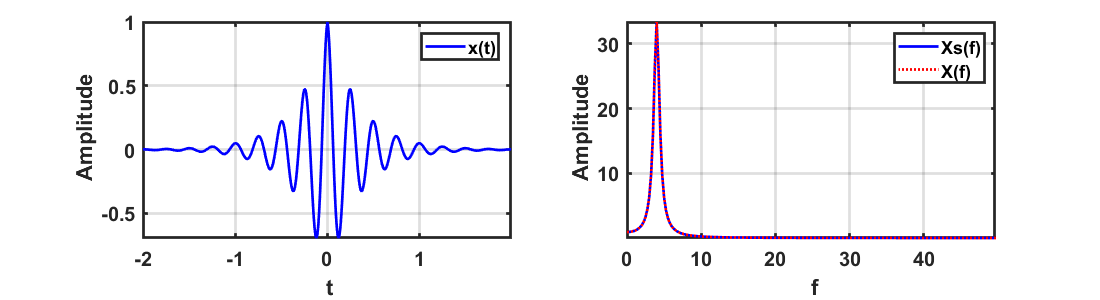

clear; clc ; close all;

a = 3;
f0 = 4;

x1 = @(t) exp(-a.*abs(t));
x2 = @(t) cos(2*pi*f0*t);
x3 = @(t) x1(t).*x2(t);

fs = 100;
dt = 1/fs;
t = -2:dt:2-dt;

xn = x3(t);
nfft = numel(xn); % there is no zero-padding. 
f = (0:nfft/2-1)*1/(nfft*dt);

% from DFT equation
Xk_fun = @(k) sum(xn.*exp(-sqrt(-1)*2*pi/nfft*k*(1:nfft)),2);        
Xk = Xk_fun([0:nfft/2-1]');

% use of a 'fft' function
X_fft = fft(xn, nfft);

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 300]);

subplot(121);plot(t,x3(t),'-b', 'linewidth', 2);
legend('x(t)');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf t');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(122);plot(f,abs(Xk),'-b', 'linewidth', 2);hold on;
plot(f,,':r', 'linewidth', 2);hold off
legend('Xs(f)', 'X(f)'); axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf f');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### Zero-padding

clear; close all; clc;

f1 = 10; f2=20; f3=21; 

fs=60; % sampling frequency

T = 1.5;
t = 0: 1/fs : T-1/fs;
x = 2*sin(2*pi*f1*t) + 2 * sin(2*pi*f2*t) + 2 * sin(2*pi*f3*t);

N = length(x);

wrect = rectwin(N);
xrect = x.*wrect';
X1 = fft(xrect);
f1 = fs*(0:N-1)/N;

fig2 = figure(2);
set(fig2,'Position', [100 100 1100 700]);

subplot(311); plot(t,x, 'b', 'linewidth', 1);
axis tight;grid ;on; hold off;
ylabel('\bf x(t)'); 
xlabel('\bf Time(s)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

subplot(312);plot(f1(1:N/2+1), 2*abs(X1(1:N/2+1)/fs/T), '-ob', 'linewidth', 1)
axis tight;grid on; hold off;
legend(sprintf('nfft = %d',N))
ylabel('\bf X(f)'); 
xlabel('\bf f (Hz)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

nfft = 2048;
X2 = fft(xrect, nfft);
f2 = fs*(0:nfft-1)/nfft;

subplot(313);plot(f2(1:nfft/2+1), 2*abs(X2(1:nfft/2+1)/fs/T), '-ob', 'linewidth', 1)
axis tight;grid on; hold off;
legend(sprintf('nfft = %d',nfft))
ylabel('\bf X(f)'); 
xlabel('\bf f (Hz)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');